# Copter. Rate + Attitude loop + Mixer + Actuator dynamic

clc; clear; close all;

%% ============================================================
%  QUADCOPTER ATTITUDE + RATE PID WITH MIXER AND MOTOR LAG
%  States:
%     x = [phi; theta; psi; p; q; r; F1; F2; F3; F4]
%  where Fi are actual motor thrusts [N]
% =============================================================

%% Initial data
% NED-style attitude naming:
% roll = phi, pitch = theta, yaw = psi

m = 2.0;                                 % kg
g = 9.81;                                % m/s^2
J = diag([0.01 0.01 0.002]);             % kg*m^2
Cw = diag([0.01 0.01 0.01]);             % rotational damping

Ts = 0.01;
Tf = 5;
tspan = 0:Ts:Tf;
N = numel(tspan);

% Geometry
side = 0.25;                             % 250 mm square side
a = side/2;                              % half-side [m]

% Motor coordinates [x y] in body frame
% x forward, y right
r1 = [ a;  a];    % motor 1: front-right
r2 = [-a; -a];    % motor 2: back-left
r3 = [ a; -a];    % motor 3: front-left
r4 = [-a;  a];    % motor 4: back-right

motor_pos = [r1, r2, r3, r4];

% Spin directions: CCW = +1, CW = -1
% 1 CCW, 2 CCW, 3 CW, 4 CW
spin_dir = [ 1; 1; -1; -1 ];

% Yaw drag torque coefficient:
% Qi = spin_i * c_tau * Fi
% This is a simplified mapping between thrust and reaction torque.
c_tau = 0.02;                            % [m], tunable simplified coefficient

% Motor lag
tau_m = 0.05;                            % motor thrust time constant [s]

% Thrust limits
Fmin = 0.0;                              % N
Fmax = 15.0;                             % N per motor

%% Controller gains

% -------- Inner rate PID --------
Kp_rate = [0.12; 0.12; 0.02];
Ki_rate = [0.00; 0.00; 0.00];
Kd_rate = [0.002; 0.002; 0.001];

% -------- Outer attitude PID --------
Kp_att = [0.10; 0.10; 0.02];
Ki_att = [0.00; 0.00; 0.00];
Kd_att = [0.002; 0.002; 0.001];

% Rate reference saturation
rate_ref_lim = deg2rad([100; 100; 80]);   % [p q r] limits

## Parameters struct

param.J = J;
param.m = m;
param.g = g;
param.Cw = Cw;
param.Ts = Ts;

param.motor_pos = motor_pos;
param.spin_dir = spin_dir;
param.c_tau = c_tau;
param.tau_m = tau_m;
param.Fmin = Fmin;
param.Fmax = Fmax;

param.rate.Kp = Kp_rate;
param.rate.Ki = Ki_rate;
param.rate.Kd = Kd_rate;
param.rate.lim = rate_ref_lim;

param.att.Kp = Kp_att;
param.att.Ki = Ki_att;
param.att.Kd = Kd_att;

## Initial conditions

eul0  = deg2rad([5; 0; 0]);              % [phi; theta; psi]
rate0 = deg2rad([0; 2; 0]);              % [p; q; r]

## Simulation

% Start motors at hover thrust
F_hover = m*g/4;
Fmot0 = [F_hover; F_hover; F_hover; F_hover];

xIC = [eul0; rate0; Fmot0];

%% Memory
x_history = zeros(length(xIC), N);
x_history(:,1) = xIC;

u_moment_hist   = zeros(3, N-1);         % commanded body moments
u_alloc_hist    = zeros(4, N-1);         % [Tcol; Mx; My; Mz]
Fcmd_hist       = zeros(4, N-1);         % commanded motor thrusts
Fact_hist       = zeros(4, N);           % actual motor thrusts
Fact_hist(:,1)  = Fmot0;

att_err_hist    = zeros(3, N-1);
rate_err_hist   = zeros(3, N-1);
rate_ref_hist   = zeros(3, N-1);

%% Controller states
state_att.integral  = zeros(3,1);
state_att.prevError = zeros(3,1);

state_rate.integral  = zeros(3,1);
state_rate.prevError = zeros(3,1);

%% References
eul_ref = deg2rad([0; 0; 0]);            % desired [roll; pitch; yaw]

%% Simulation loop
for k = 1:N-1

    x_true = x_history(:,k);

    eul  = x_true(1:3);
    rate = x_true(4:6);
    Fmot = x_true(7:10);

    % =========================================================
    % Outer attitude loop -> desired body rates
    % =========================================================
    att_err = angle_error(eul_ref, eul);

    [rate_setpoint, state_att] = pid_controller(att_err, state_att, ...
        param.att.Kp, param.att.Ki, param.att.Kd, param.Ts);

    rate_ref = min(max(rate_setpoint, -param.rate.lim), param.rate.lim);

    % =========================================================
    % Inner rate loop -> desired body moments
    % =========================================================
    rate_err = rate_ref - rate;

    [M_cmd, state_rate] = pid_controller(rate_err, state_rate, ...
        param.rate.Kp, param.rate.Ki, param.rate.Kd, param.Ts);

    % =========================================================
    % Collective thrust
    % For now keep it at hover (attitude-only test)
    % =========================================================
    Tcol_cmd = m*g;

    % Desired virtual control vector
    u_alloc = [Tcol_cmd; M_cmd];

    % =========================================================
    % Mixer: [Tcol; Mx; My; Mz] -> motor thrust commands
    % =========================================================
    F_cmd = mixer_quad_X(u_alloc, param);

    % Saturate motor commands
    F_cmd = min(max(F_cmd, param.Fmin), param.Fmax);

    % =========================================================
    % Integrate plant
    % =========================================================
    xdot_g = @(t, x) copter_dyn_motors(x, F_cmd, param);
    [~, xSol] = ode45(xdot_g, [0 Ts], x_true);

    x_next = xSol(end,:)';

    % Wrap yaw
    x_next(3) = wrapToPi(x_next(3));

    % Prevent actual thrust states from numerical drift outside bounds
    x_next(7:10) = min(max(x_next(7:10), param.Fmin), param.Fmax);

    % =========================================================
    % Store
    % =========================================================
    x_history(:,k+1) = x_next;

    u_moment_hist(:,k) = M_cmd;
    u_alloc_hist(:,k) = u_alloc;
    Fcmd_hist(:,k) = F_cmd;
    Fact_hist(:,k+1) = x_next(7:10);

    att_err_hist(:,k) = att_err;
    rate_err_hist(:,k) = rate_err;
    rate_ref_hist(:,k) = rate_ref;
end

## Plot attitude and rates

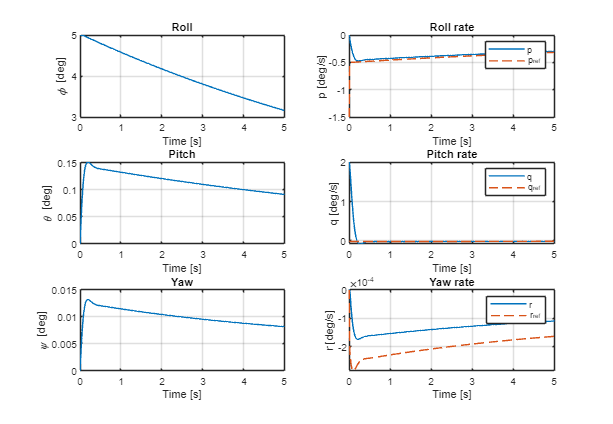

figure('Position',[150 100 1300 900]);

subplot(3,2,1);
plot(tspan, rad2deg(x_history(1,:)), 'LineWidth', 1.2); grid on;
xlabel('Time [s]'); ylabel('\phi [deg]'); title('Roll');

subplot(3,2,3);
plot(tspan, rad2deg(x_history(2,:)), 'LineWidth', 1.2); grid on;
xlabel('Time [s]'); ylabel('\theta [deg]'); title('Pitch');

subplot(3,2,5);
plot(tspan, rad2deg(x_history(3,:)), 'LineWidth', 1.2); grid on;
xlabel('Time [s]'); ylabel('\psi [deg]'); title('Yaw');

subplot(3,2,2);
plot(tspan, rad2deg(x_history(4,:)), 'LineWidth', 1.2); hold on;
plot(tspan(1:end-1), rad2deg(rate_ref_hist(1,:)), '--', 'LineWidth', 1.2);
grid on; xlabel('Time [s]'); ylabel('p [deg/s]'); title('Roll rate');
legend('p','p_{ref}');

subplot(3,2,4);
plot(tspan, rad2deg(x_history(5,:)), 'LineWidth', 1.2); hold on;
plot(tspan(1:end-1), rad2deg(rate_ref_hist(2,:)), '--', 'LineWidth', 1.2);
grid on; xlabel('Time [s]'); ylabel('q [deg/s]'); title('Pitch rate');
legend('q','q_{ref}');

subplot(3,2,6);
plot(tspan, rad2deg(x_history(6,:)), 'LineWidth', 1.2); hold on;
plot(tspan(1:end-1), rad2deg(rate_ref_hist(3,:)), '--', 'LineWidth', 1.2);
grid on; xlabel('Time [s]'); ylabel('r [deg/s]'); title('Yaw rate');
legend('r','r_{ref}');

## Plot torques

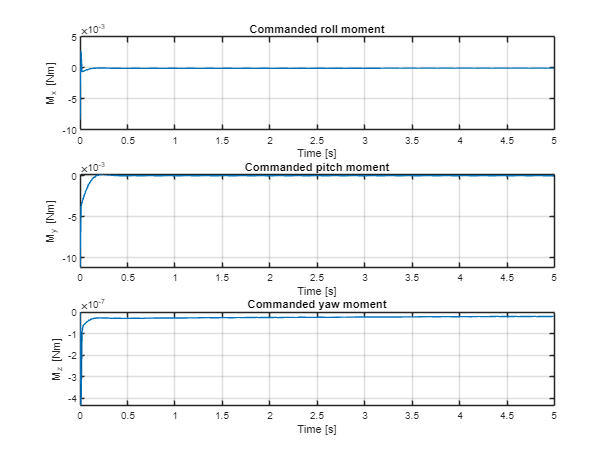

figure('Position',[200 100 1200 900]);

subplot(3,1,1);
plot(tspan(1:end-1), u_moment_hist(1,:), 'LineWidth', 1.2); grid on;
xlabel('Time [s]'); ylabel('M_x [Nm]'); title('Commanded roll moment');

subplot(3,1,2);
plot(tspan(1:end-1), u_moment_hist(2,:), 'LineWidth', 1.2); grid on;
xlabel('Time [s]'); ylabel('M_y [Nm]'); title('Commanded pitch moment');

subplot(3,1,3);
plot(tspan(1:end-1), u_moment_hist(3,:), 'LineWidth', 1.2); grid on;
xlabel('Time [s]'); ylabel('M_z [Nm]'); title('Commanded yaw moment');

## Plot forces

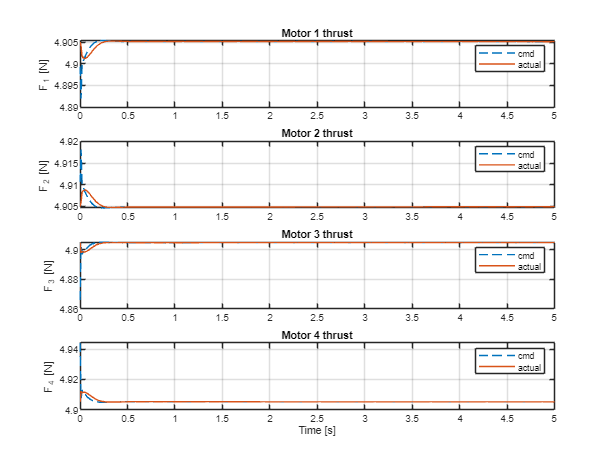

figure('Position',[200 100 1200 900]);

subplot(4,1,1);
plot(tspan(1:end-1), Fcmd_hist(1,:), '--', 'LineWidth', 1.2); hold on;
plot(tspan, Fact_hist(1,:), 'LineWidth', 1.2); grid on;
ylabel('F_1 [N]'); title('Motor 1 thrust'); legend('cmd','actual');

subplot(4,1,2);
plot(tspan(1:end-1), Fcmd_hist(2,:), '--', 'LineWidth', 1.2); hold on;
plot(tspan, Fact_hist(2,:), 'LineWidth', 1.2); grid on;
ylabel('F_2 [N]'); title('Motor 2 thrust'); legend('cmd','actual');

subplot(4,1,3);
plot(tspan(1:end-1), Fcmd_hist(3,:), '--', 'LineWidth', 1.2); hold on;
plot(tspan, Fact_hist(3,:), 'LineWidth', 1.2); grid on;
ylabel('F_3 [N]'); title('Motor 3 thrust'); legend('cmd','actual');

subplot(4,1,4);
plot(tspan(1:end-1), Fcmd_hist(4,:), '--', 'LineWidth', 1.2); hold on;
plot(tspan, Fact_hist(4,:), 'LineWidth', 1.2); grid on;
ylabel('F_4 [N]'); xlabel('Time [s]'); title('Motor 4 thrust'); legend('cmd','actual');

## Functions

function rot = E2W(ang)
    % Euler rate mapping for 3-2-1 sequence:
    % yaw(Z) -> pitch(Y) -> roll(X)
    roll  = ang(1);
    pitch = ang(2);

    rot = [ ...
        cos(pitch),  sin(roll)*sin(pitch),  cos(roll)*sin(pitch);
        0,           cos(roll)*cos(pitch), -sin(roll)*cos(pitch);
        0,           sin(roll),             cos(roll) ] / cos(pitch);
end

function [u, state] = pid_controller(e, state, Kp, Ki, Kd, Ts)
    state.integral = state.integral + e .* Ts;
    derivative = (e - state.prevError) ./ Ts;
    u = Kp .* e + Ki .* state.integral + Kd .* derivative;
    state.prevError = e;
end

function e = angle_error(ref, ang)
    e = ref - ang;
    e(1) = wrapToPi(e(1));
    e(2) = wrapToPi(e(2));
    e(3) = wrapToPi(e(3));
end

function F_cmd = mixer_quad_X(u_alloc, p)
    % u_alloc = [Tcol; Mx; My; Mz]
    %
    % Build allocation matrix:
    % [Tcol]   [ 1   1   1   1 ] [F1]
    % [ Mx ] = [ y1 y2 y3 y4 ] [F2]
    % [ My ]   [-x1-x2-x3-x4 ] [F3]
    % [ Mz ]   [s1c s2c s3c s4c] [F4]
    %
    % with si = spin direction, c = c_tau

    x = p.motor_pos(1,:).';
    y = p.motor_pos(2,:).';
    s = p.spin_dir(:);
    c = p.c_tau;

    B = [ ...
        1,      1,      1,      1;
        -y(1),   -y(2),   -y(3),   -y(4);
       x(1),  x(2),  x(3),  x(4);
        s(1)*c, s(2)*c, s(3)*c, s(4)*c ];

    F_cmd = B \ u_alloc;
end

function xdot = copter_dyn_motors(x, F_cmd, p)
    % States
    eul  = x(1:3);
    rate = x(4:6);
    Fmot = x(7:10);       % actual motor thrusts [N]

    % ----------------------------------------------------------
    % Motor lag
    % ----------------------------------------------------------
    Fdot = (F_cmd - Fmot) / p.tau_m;

    % ----------------------------------------------------------
    % Actual moments from actual motor thrusts
    % ----------------------------------------------------------
    M = motor_thrusts_to_moments(Fmot, p);

    % ----------------------------------------------------------
    % Rotational dynamics
    % ----------------------------------------------------------
    eul_dot  = E2W(eul) * rate;
    rate_dot = p.J \ (-p.Cw * rate - cross(rate, p.J*rate) + M);

    xdot = [eul_dot; rate_dot; Fdot];
end

function M = motor_thrusts_to_moments(Fmot, p)
    % Computes body moments [Mx; My; Mz] from motor thrusts
    x = p.motor_pos(1,:).';
    y = p.motor_pos(2,:).';
    s = p.spin_dir(:);

    Mx = sum(-y .* Fmot);
    My = sum(x .* Fmot);
    Mz = sum(s .* p.c_tau .* Fmot);

    M = [Mx; My; Mz];
end